# Surface Normal Hough Transform Animation

David Olson, 20 Mar 2021

Demonstrating the basics of the Surface Normal Hough Transform (SNHT) and how it works.  

close all
clear all

## Detecting a Plane using the SNHT

Suppose you are given an unorganized list of $\left\langle x,y,z\right\rangle$ points.  By looking at this list, how can you determine whether or not a plane is present in this list of points?  The standard method to detect parameterized objects such as a plane is the Hough Transform.  

In our scenario, our SNHT will take points in $\left\langle x,y,z\right\rangle$and convert them into the $\left\langle \phi \;,\theta \;,\rho \;\right\rangle$as a means of detecting the plane.  In our specific application, we are interested in detecting a floor.  This floor may be subject to slight amounts of roll $\left(\phi \;\right)\;$and pitch $\left(\theta \;\right)$ which is something that requires detecting.  

Using the parameterization (maybe write the derivation in here later if its really needed) determined last week:


$$\rho =\sin \left(\theta \right)x-\sin \left(\phi \right)\cos \left(\theta \right)y\;+\cos \left(\phi \right)\cos \left(\theta \right)z$$


By rotating through a search space of $\phi$ and $\theta \;$we calculate different possibilites of $\rho$.  Once having processed multiple points, the intersections of $\rho$ determine the true roll and pitch of the plane.  

## Step-by-Step Example of using the SNHT

Suppose we only have three points, which make up a plane.  $A=\left\langle 1,1,0\right\rangle ,B=\left\langle 2,1,0\right\rangle ,C=\;\left\langle 1,2,0\right\rangle$

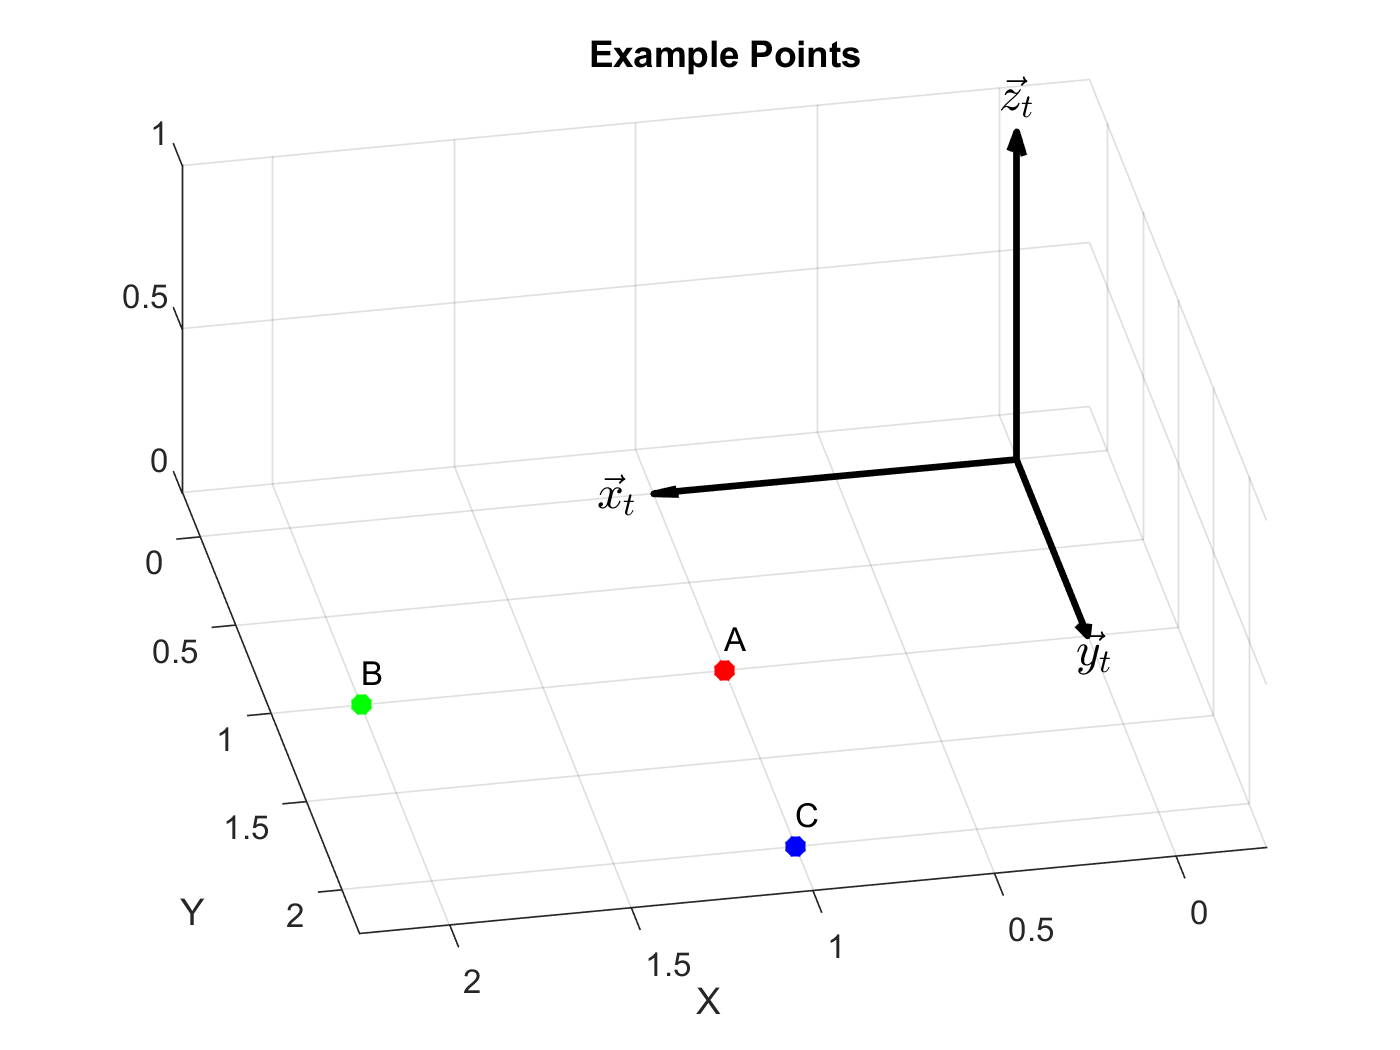

% Example Plane Points
A = [1; 1; 0];
B = [2; 1; 0];
C = [1; 2; 0];
xyz = [A, B, C];
color_str = ['r', 'g', 'b'];

% Plot Example Starting Point
figure
hold on
plot3(A(1), A(2), A(3), 'r*', 'LineWidth', 3)
plot3(B(1), B(2), B(3), 'g*', 'LineWidth', 3)
plot3(C(1), C(2), C(3), 'b*', 'LineWidth', 3)
plot_frame(eye(3), zeros(3,1), 't', 'k');
text(A(1), A(2), A(3)+0.1, 'A')
text(B(1), B(2), B(3)+0.1, 'B')
text(C(1), C(2), C(3)+0.1, 'C')
title('Example Points')
xlabel('X')
ylabel('Y')
xlim([-0.25, 2.25])
ylim([-0.25, 2.25])
grid on
view([168.960 53.906])
hold off

Obviously, it is easy to determine the parameterization of this plane, since it does not experience any pitch or roll.  Therefore, we know the answer going into the start of this problem.  But can the SNHT confirm the obvious?

### Converting Point "A" into the Hough Space

The process of bringing the point "A" into the Hough Space $\left\langle x,y,z\right\rangle$ $\longrightarrow$$\left\langle \phi \;,\theta \;,\rho \;\right\rangle$works as follows

- Start with the $\left\langle x,y,z\right\rangle$ point $A=\left\langle 1,1,0\right\rangle$

- We define a search space for the bounds of $\phi$ and $\theta \;$ 


$$\phi_l <\phi <\phi_u ,\;\;\;\;\;\;\;\theta_l <\theta <\theta_u$$



$$-{30}^{\circ } <\phi <{30}^{\circ } ,\;\;\;\;\;\;-{30}^{\circ } <\theta <{30}^{\circ }$$


- With our $\left\langle x,y,z\right\rangle$ point and defining our search space, we have 5 knowns and 1 unknown

- We iterate through all possibilites of $\phi$ and $\theta \;$to calculate the different values of $\rho \;$given the following parameterization


$$\rho =\sin \left(\theta \right)x-\sin \left(\phi \right)\cos \left(\theta \right)y\;+\cos \left(\phi \right)\cos \left(\theta \right)z$$


- Having done so, this generates a sinusoidal plane in the Hough Space

Check out the following animation for a visual demonstration

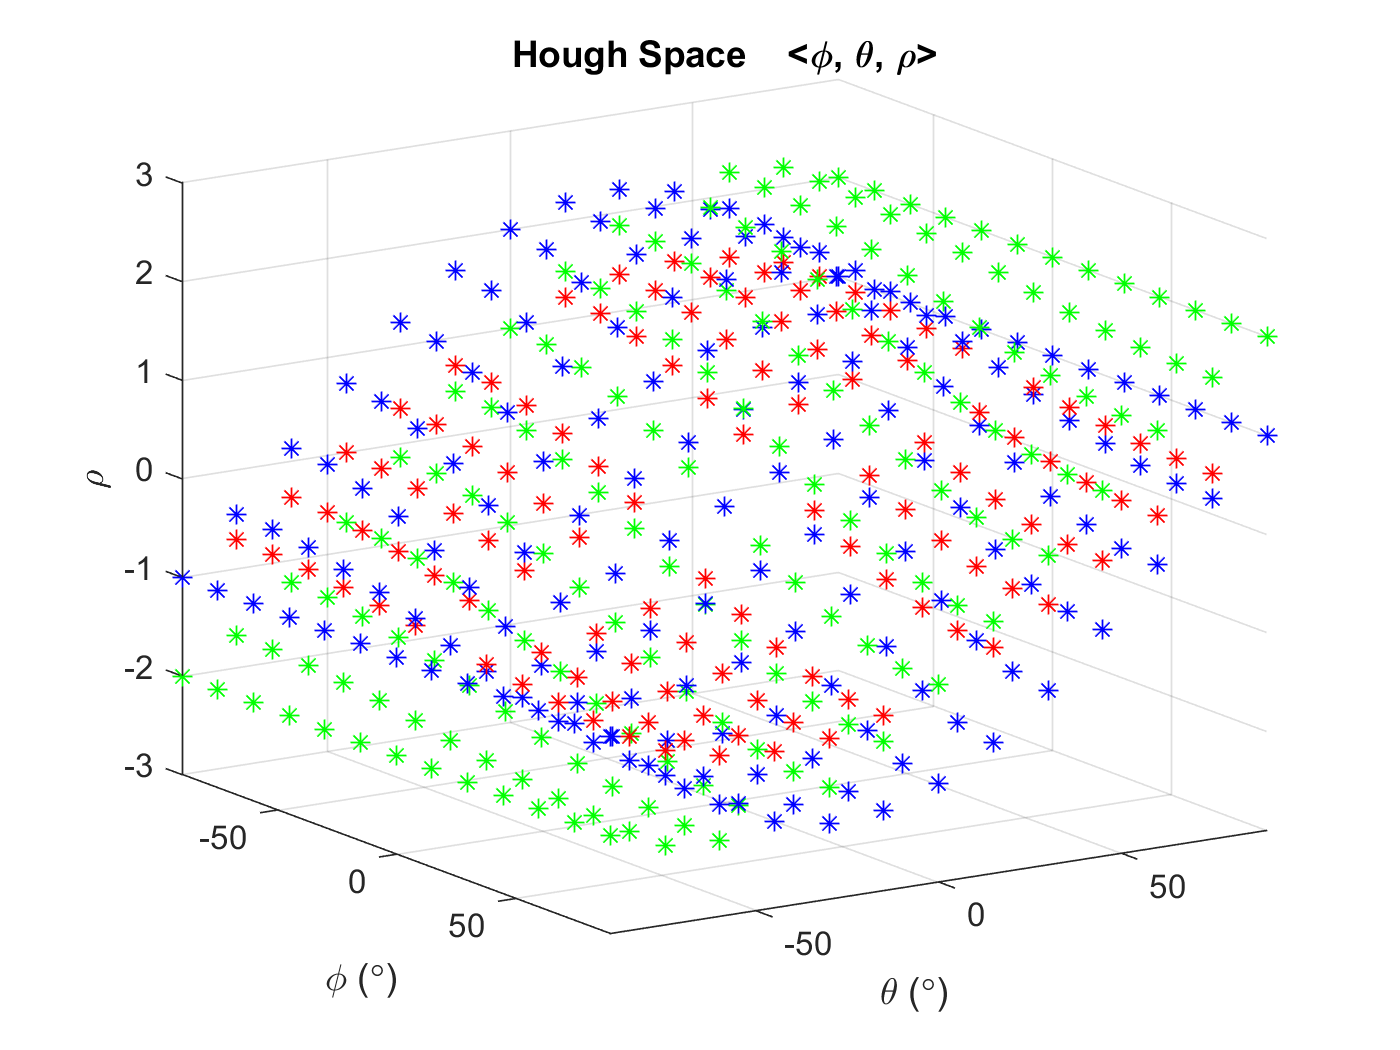

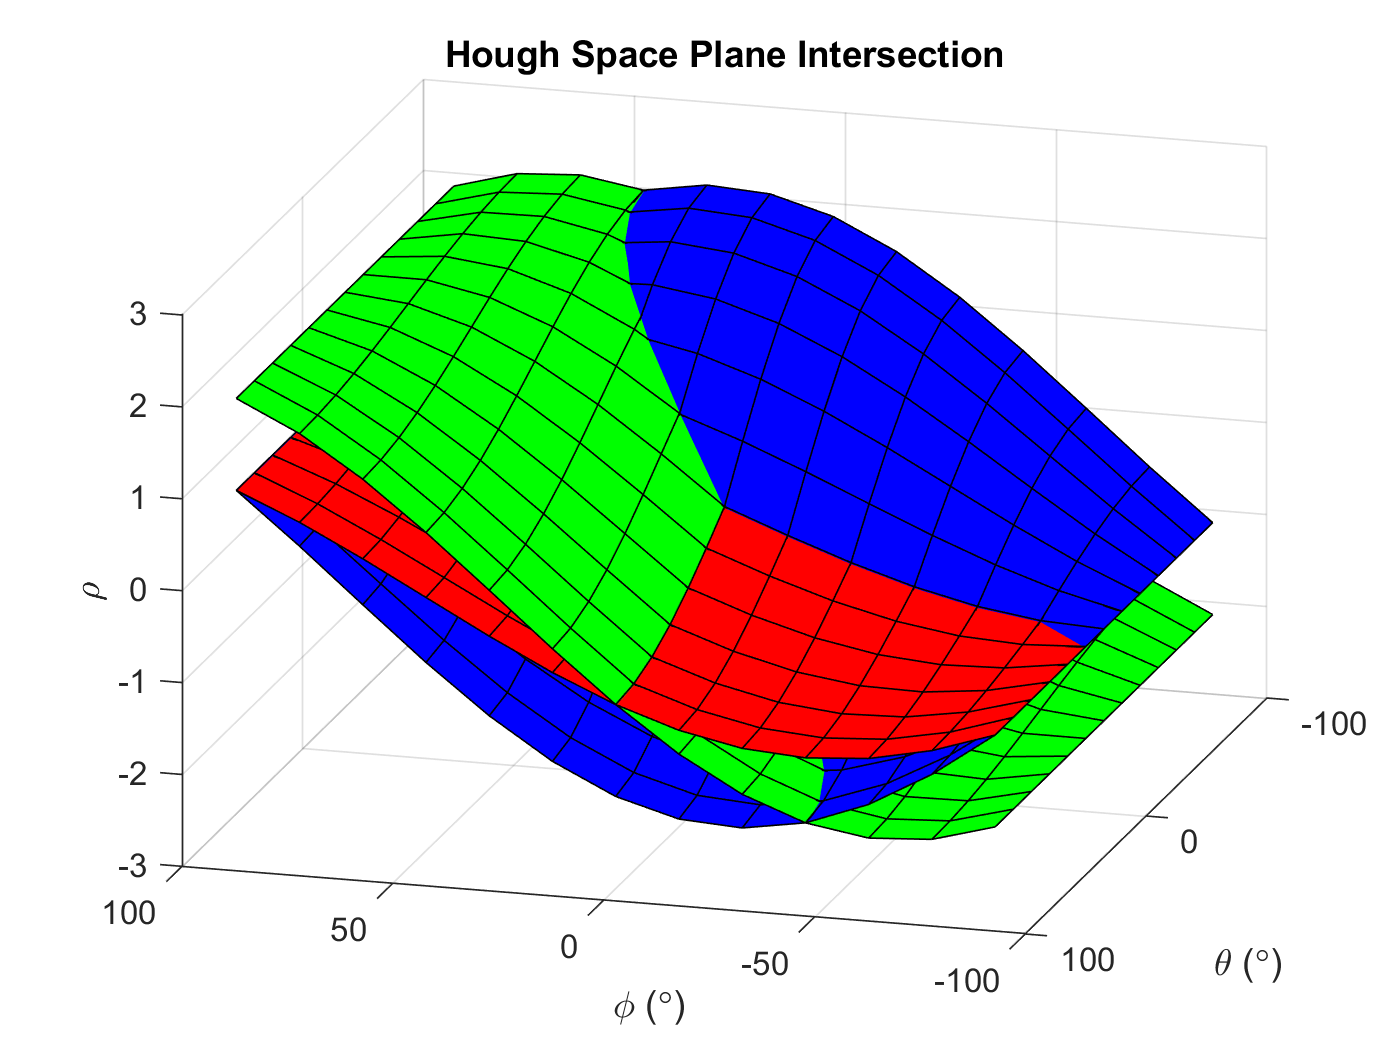

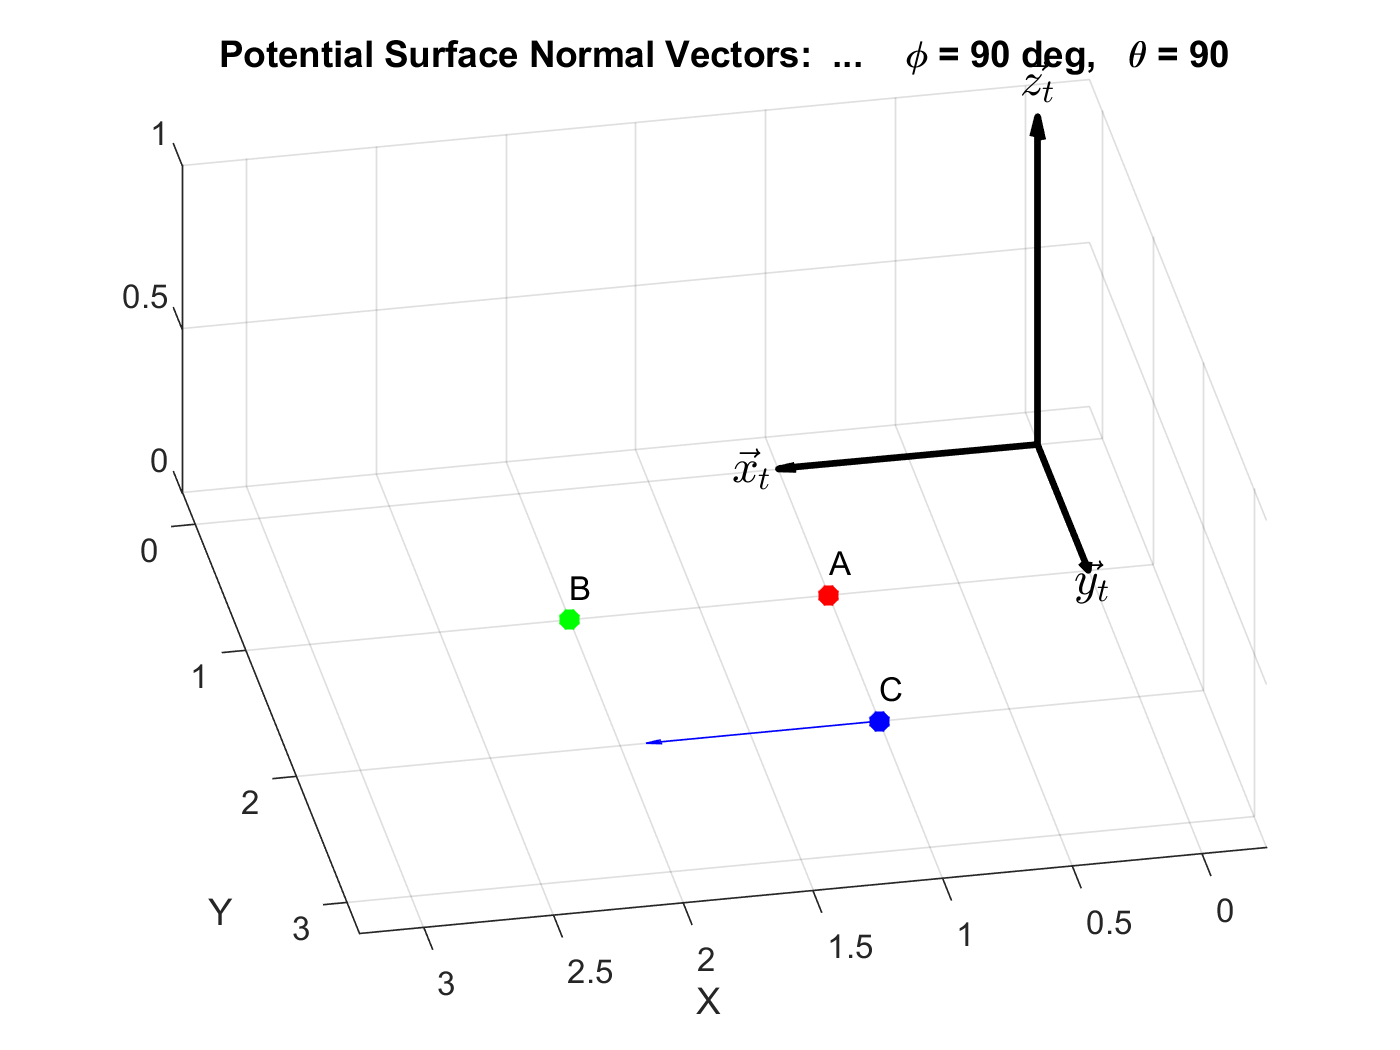

% Define the Hough Search Space
phi = (-90 : 15 : 90) * pi/180;
theta = (-90 : 15 : 90) * pi/180;
rho = zeros(length(phi), length(theta), 3);

% Animation Parameters
pause_time = 0.1;
[X, Y] = meshgrid(phi * 180/pi, theta * 180/pi);

% Begin Animation
for k = 1 : 3
    for ii = 1 : length(phi)
        for jj = 1 : length(theta)
            
            % Create Values for Surface Normal Animation
            uwv = rotate_x(phi(ii)) * rotate_y(theta(jj)) * [0; 0; 1];
            
            % Example Plot Number 1
            figure(2)
            hold on
            plot3(A(1), A(2), A(3), 'r*', 'LineWidth', 3)
            plot3(B(1), B(2), B(3), 'g*', 'LineWidth', 3)
            plot3(C(1), C(2), C(3), 'b*', 'LineWidth', 3)
            quiver3(xyz(1,k), xyz(2,k), xyz(3,k), ...
                    uwv(1), uwv(2), uwv(3), ...
                    'Color', color_str(k))
            hg = plot_frame(eye(3), zeros(3,1), 't', 'k');
            text(A(1), A(2), A(3)+0.1, 'A')
            text(B(1), B(2), B(3)+0.1, 'B')
            text(C(1), C(2), C(3)+0.1, 'C')
            title(['Potential Surface Normal Vectors:  ...' ...
                '    \phi = ', num2str(phi(ii)*180/pi), ...
                ' deg,   \theta = ', num2str(theta(jj)*180/pi)])
            xlabel('X')
            ylabel('Y')
            xlim([-0.25, 3.25])
            ylim([-0.25, 3.25])
            grid on
            view([168.960 53.906])
            hold off
            
            % Convert into the Hough Space
            rho(ii,jj,k) = sin(theta(jj))*xyz(1,k) - ...
                sin(phi(ii))*cos(theta(jj))*xyz(2,k) + ...
                cos(phi(ii))*cos(theta(jj))*xyz(3,k);
            
            % Example Plot 2
            figure(3)
            hold on
            cs = [color_str(k), '*'];
            plot3(phi(ii)*180/pi, theta(jj)*180/pi, rho(ii,jj,k), cs)
            title('Hough Space    <\phi, \theta, \rho>')
            xlabel('\phi (\circ)')
            ylabel('\theta (\circ)')
            zlabel('\rho')
            xlim([phi(1) phi(end)] * 180/pi)
            ylim([theta(1) theta(end)] * 180/pi)
            grid on
            view([56.88 17.83])
            hold off
            
            % Pause Animation
            if (k == 1)
                pause_time = 0.1;
            else 
                pause_time = 0.01;
            end
            pause(pause_time)
            
            % Clearing Plots
            if ((ii ~= length(phi)) || (jj ~= length(theta)))
                clf(2)
            end
            
        end
    end
    
    % Hough Plane Intersection
    figure(4)
    hold on
    surf(X, Y, rho(:,:,k), 'FaceColor', color_str(k))
    title('Hough Space Plane Intersection')
    xlabel('\phi (\circ)')
    ylabel('\theta (\circ)')
    zlabel('\rho')
    grid on
    view(-164, 24)
    hold off
    
end